clear; close all;

## Lab 5 Write Up

### Harrison Robel, Partner: Karen Gong

## LHC Summary

The quest to complete the subatomic standard model and find the higgs boson lead to the construction of one of humanities greatest physics experiment. The Large Hadron Collider is a massive project which allows physicists to search for subatomic particles. The LHC accomplishes this goal by smashing together clusters of protons together at 0.999997 times the speed of light. There are two tracks where the clumps travel in opposite directions from one another, to get readings out of the particles the streams are then crossed causing collisions which occur within very large and sensitive sensors. The large amount of energy that is put into each clump allows a large range of particles to be produced, which scatter in many different directions. 

The distances within the scattering cross sections are so small that there is a unit used to describe the scattering cross section called the barn (b): $1b={10}^{-28} \;m^2$ . The rough cross section of proton-proton scattering is $0\ldotp 03b$ . The sizr of the proton-proton scattering which produces a Higgs Boson is 1 pb. This means that we need to collide a billion protons to produce a Higgs. This large number of collisions is where the need to clump protons together rises from. this allows 25 collisions per bunch at a frequency of 4GHz giving 1 billion events per second in the detectors of the LHC. This large amount of collisions leads to very high data volumes. The computers can only write around 200 MB/s which forces the ${10}^9$ number of events to 100 events per second. This gets done through the triggering system.

Triggering is a very important process at the LHC. There are multiple levels of triggers which reduce the amount of data collected. The first trigger is inside the hardware which filters out hard electrons or photons (which are not very interesting). The next level is software triggering. Software triggering uses algorithms to filter out what is important and what is not. If an event does not hit a trigger it is lost forever so it is important to have algorithms that filter out unimportant data and include the useful data. 

Another very large aspect of LHC physics are "Jets". From Matthew D. Schwartz in "TASI Lectures on Collider Physics (pg 17)" "A jet is a collection of particles that go towards the same direction in the detector." In practice there is no single definition of a jet. Ideally jets come from the same particle but sometimes it can be difficult to distinguish the mulitple jets from one another. The good thing about jets is that they allow a calculation at the parton level (quarks and gluons) to be compared to the particle level (pions and protons). Jets are ideal for algorithms that sort out particles within the detectors. The simple way to define a jet is as a cone with radius $R=\sqrt{{\left(\Delta \eta \right)}^2 +{\left(\Delta \phi \right)}^2 }$. However this is not commonly used in practice. A big issue is what particle to select as the center of the cone. There are several good choices for jet algorithms which all involve selecting a particluar particle and selecting the area to be included in the jet. The jets give us a 4-momentum which should be similar to the 4-momentum of the parton. It is also possible to form a complete classification of all particles in the jet with better angular resolution. 

To move onto the focus of this report and the purpose of the LHC in general, the Higgs Boson. The higgs has a mass of $m_h =125\ldotp 09\pm 0\ldotp 3\;\mathrm{GeV}$ . The Higgs has many different ways in which it can be produced. There are some that are very useful to Higgs detection and others that are not very useful in Higgs detection. The best way is called the "golden channel" which is $h\to {\mathrm{ZZ}}^* \to 2m_z$. This channel has very little background involved but also because the spin of the Higgs can be reproduced from this channel. This channel has very small chance of occuring. The next best channel is $\mathrm{gg}\to h\to \gamma \gamma$ which happens an order of magnitude more frequently than the first channel, but gives us a little less information. The third channel has a much larger chance of occuring. This channel cannot fully receate the higgs boson and therefore it is neccessary to use variables such as transverse mass. This channel has to have a known background. This is the channel that will require the most information and comparrison to the background, where a broad excess of Higgs need to occur. 

## Our Data

The data we have been given is two$14\;x\;100000$ matrices. One is simulated background data (QCD) and the other is simulated signal data. Each sample contains 14 features: ‘pt', 'eta', 'phi', 'mass', 'ee2', 'ee3', 'd2', 'angularity', 't1', 't2', 't3', 't21', 't32', 'KtDeltaR'. "pt" is tranverse momentum. "eta" is pseudorapidity ($\eta$). "phi" is the azimuthal angle $\left(\phi \right)$. "mass" is mass. "ee2" and "ee3" are both energy levels. "d2" is an energy correlation function. "angularity" is angularity. "t1" "t2" t21" "t32" are   

h5disp('qcd_100000_pt_1000_1200.h5')

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp('higgs_100000_pt_1000_1200.h5')

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


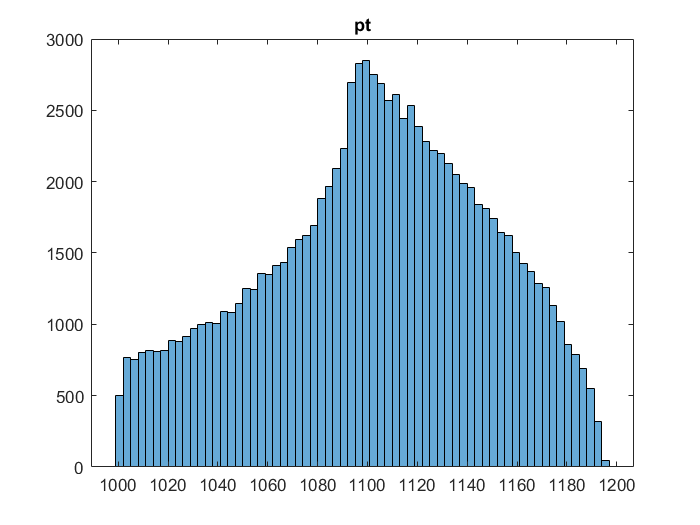

qcd = h5read('qcd_100000_pt_1000_1200.h5','/qcd_100000_pt_1000_1200');
higgs = h5read('higgs_100000_pt_1000_1200.h5','/higgs_100000_pt_1000_1200');

qcd_pt = qcd(1,:);
qcd_eta = qcd(2,:);
qcd_phi = qcd(3,:);
qcd_mass = qcd(4,:);
qcd_ee2 = qcd(5,:);
qcd_ee3 = qcd(6,:);
qcd_d2 = qcd(7,:);
qcd_angularity = qcd(8,:);
qcd_t1 = qcd(9,:);
qcd_t2 = qcd(10,:);
qcd_t3 = qcd(11,:);
qcd_t21 = qcd(12,:);
qcd_t32 = qcd(13,:);
qcd_KtDeltaR = qcd(12,:);

pt = higgs(1,:);
eta = higgs(2,:);
phi = higgs(3,:);
mass = higgs(4,:);
ee2 = higgs(5,:);
ee3 = higgs(6,:);
d2 = higgs(7,:);
angualrity = higgs(8,:);
t1 = higgs(9,:);
t2 = higgs(10,:);
t3 = higgs(11,:);
t21 = higgs(12,:);
t32 = higgs(13,:);
KtDeltaR = higgs(14,:);

histogram(pt)
title('pt')

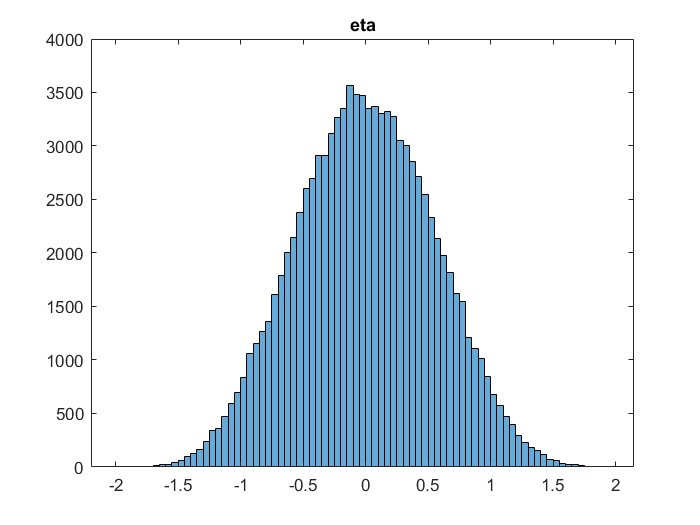

histogram(eta)
title('eta')

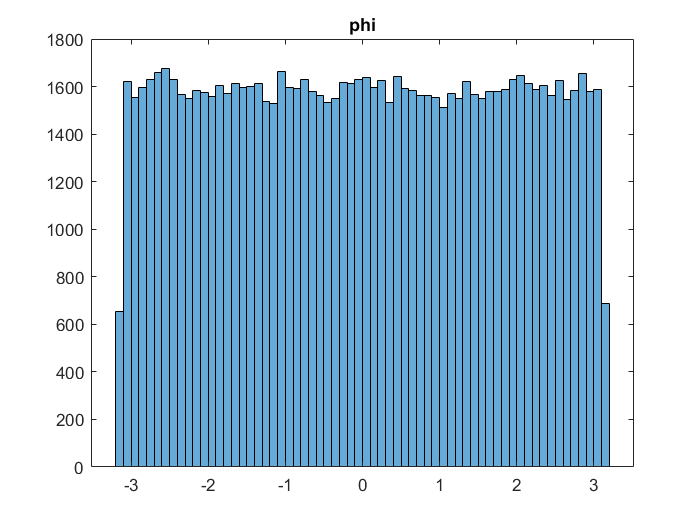

histogram(phi)
title('phi')

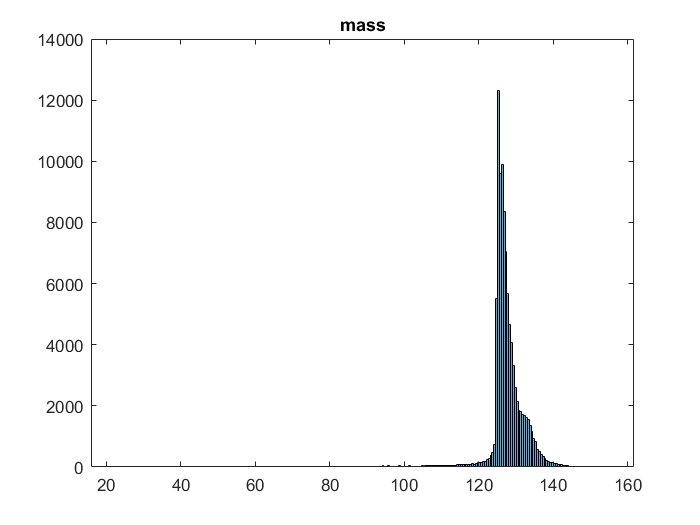

histogram(mass)
title('mass')

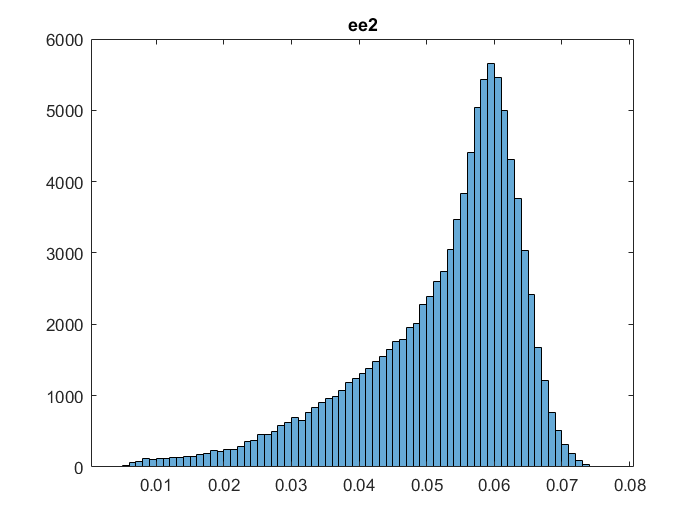

histogram(ee2)
title('ee2')

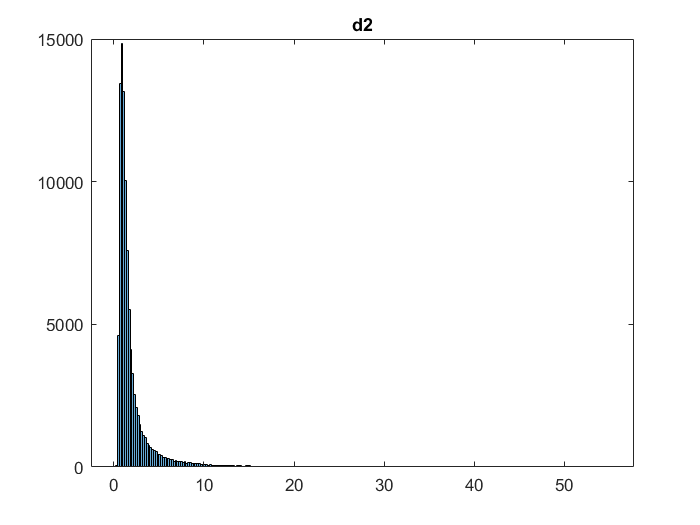

histogram(d2)
title('d2')

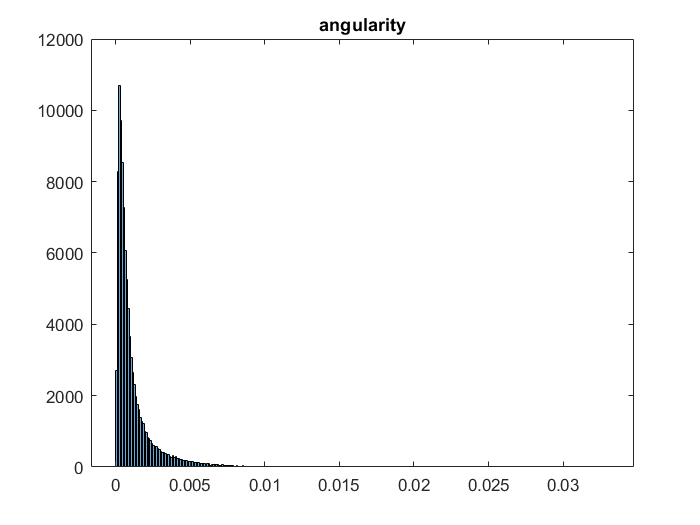

histogram(angualrity)
title('angularity')

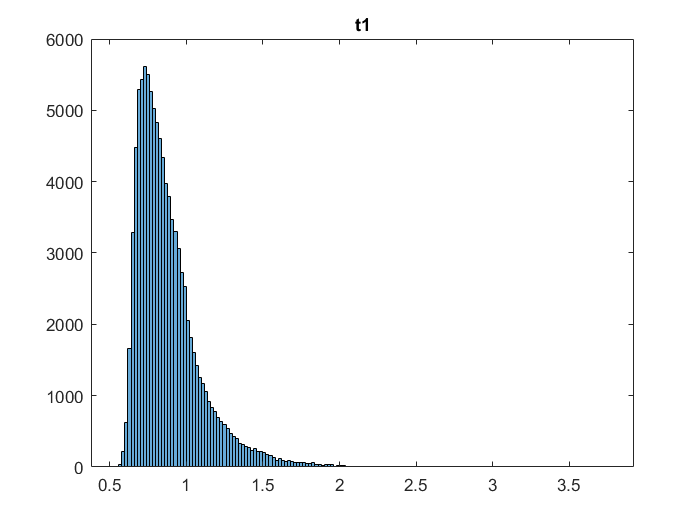

histogram(t1)
title('t1')

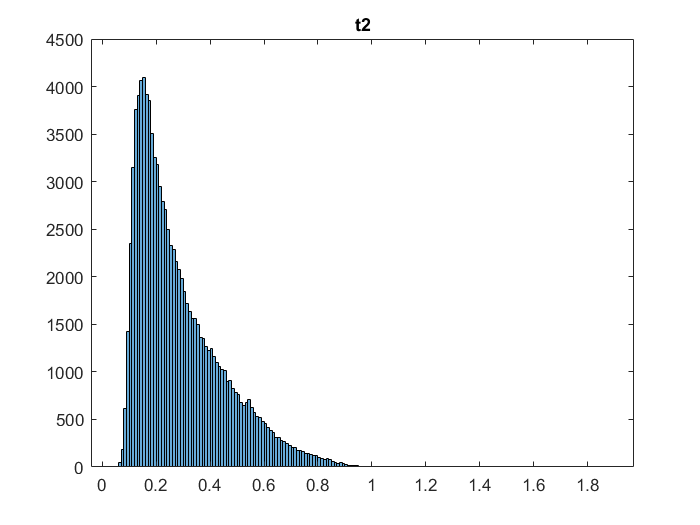

histogram(t2)
title('t2')

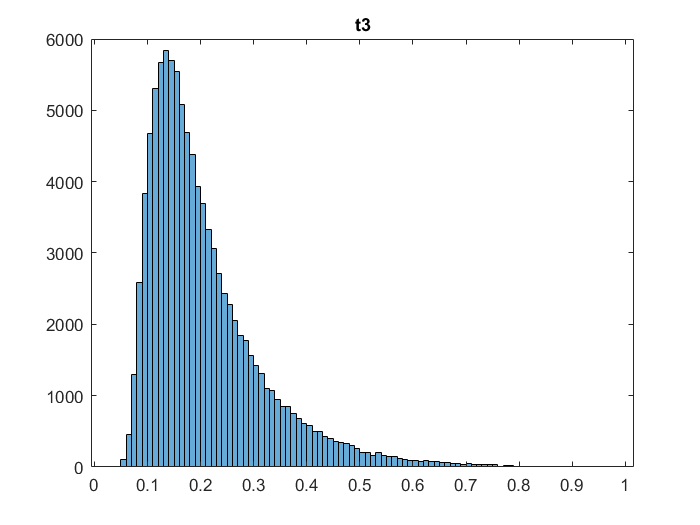

histogram(t3)
title('t3')

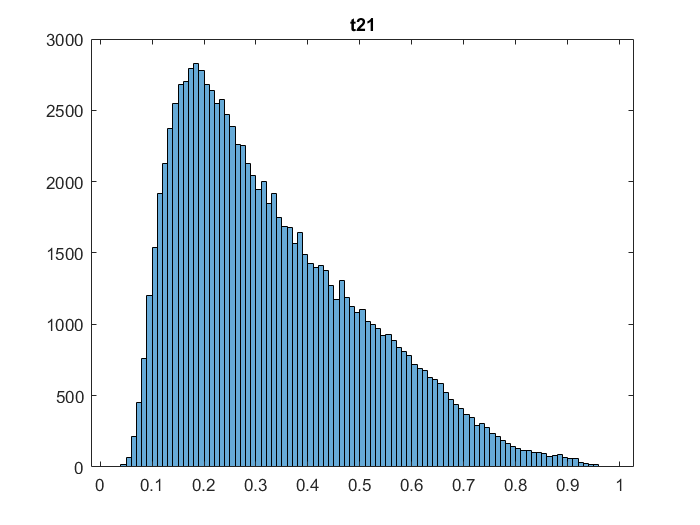

histogram(t21)
title('t21')

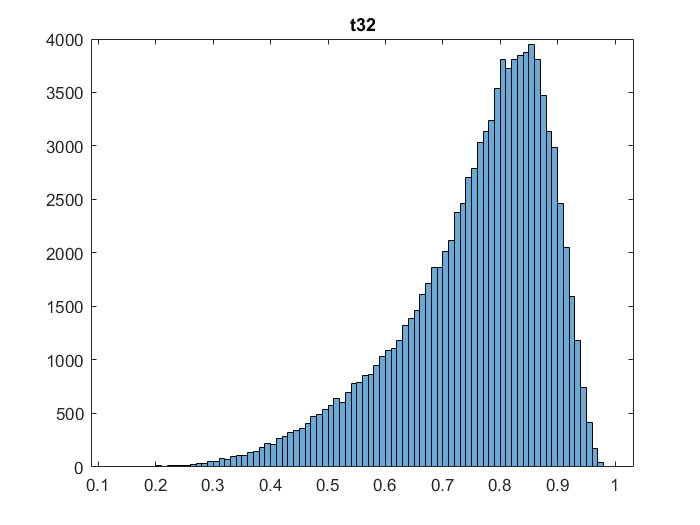

histogram(t32)
title('t32')

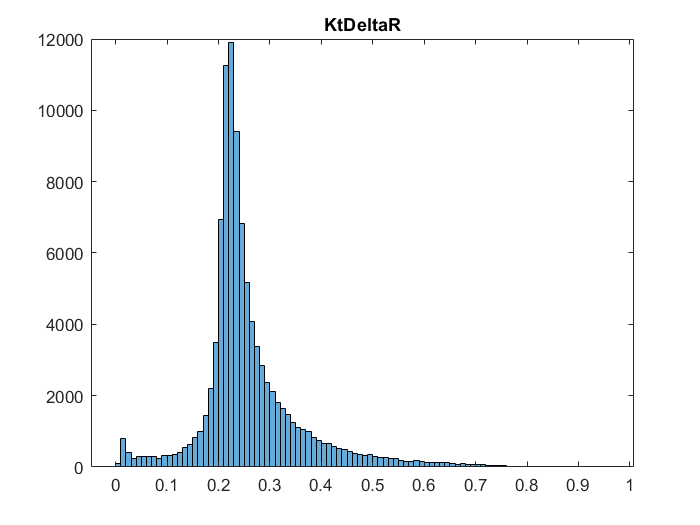

histogram(KtDeltaR)
title('KtDeltaR')

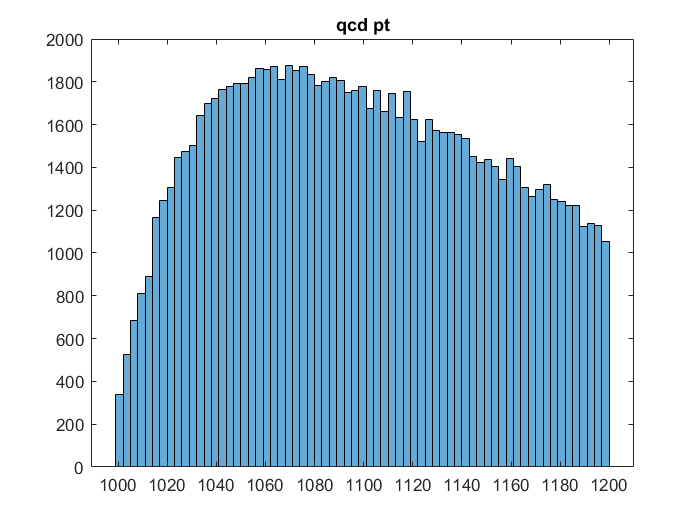


histogram(qcd_pt)
title('qcd pt')

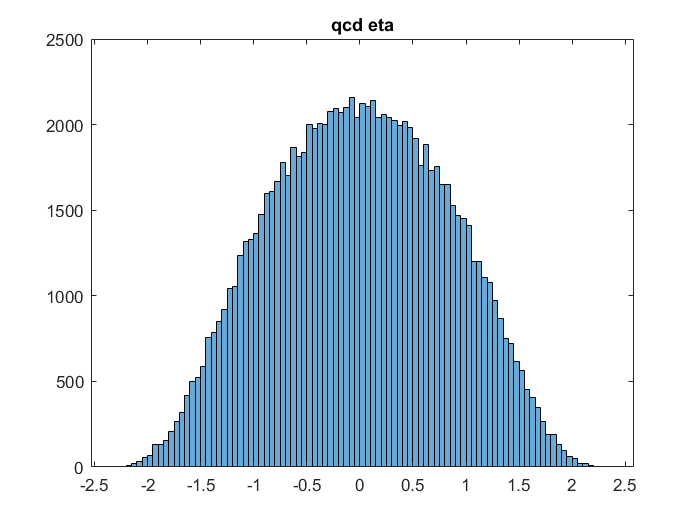

histogram(qcd_eta)
title('qcd eta')

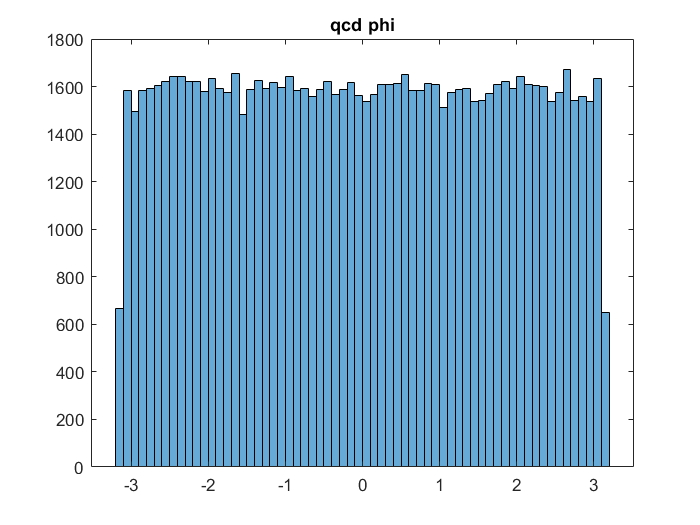

histogram(qcd_phi)
title('qcd phi')

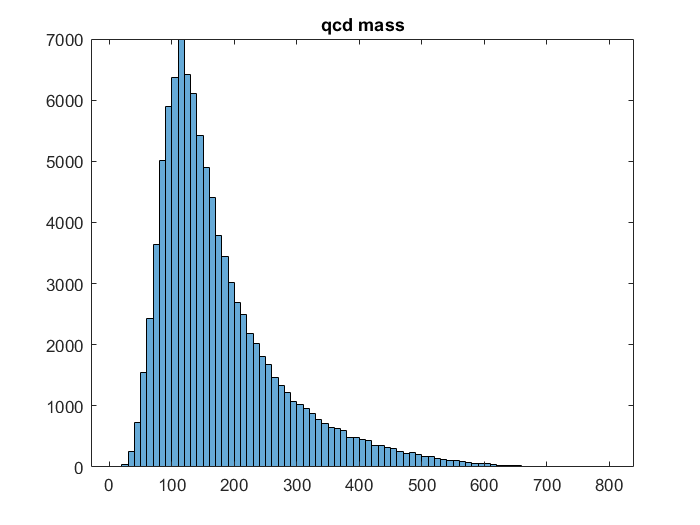

histogram(qcd_mass)
title('qcd mass')

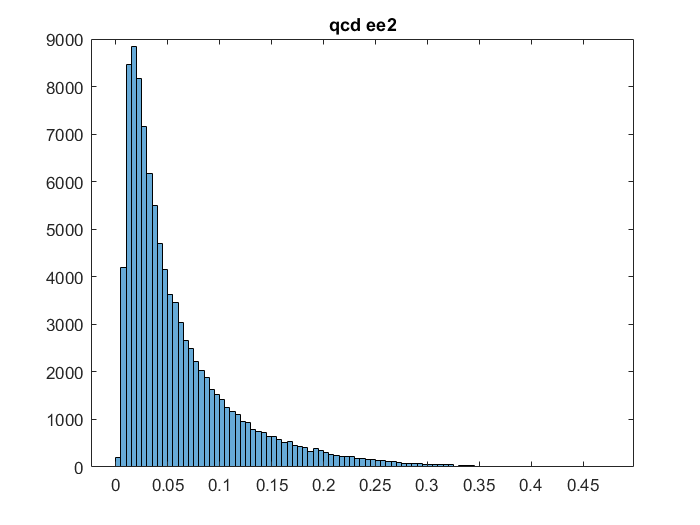

histogram(qcd_ee2)
title('qcd ee2')

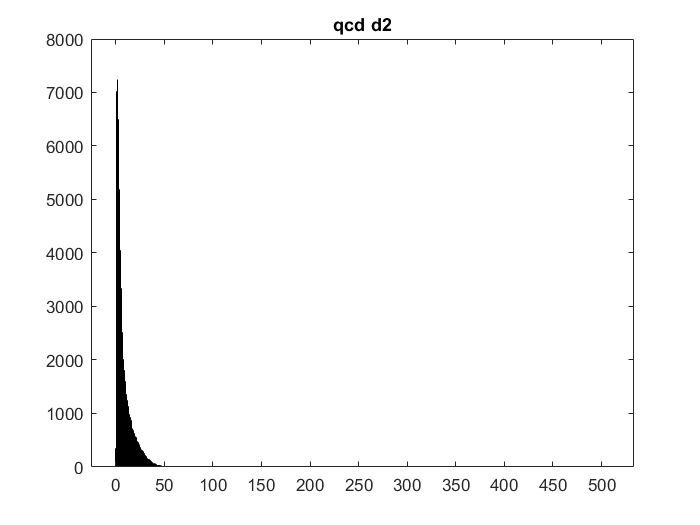

histogram(qcd_d2)
title('qcd d2')

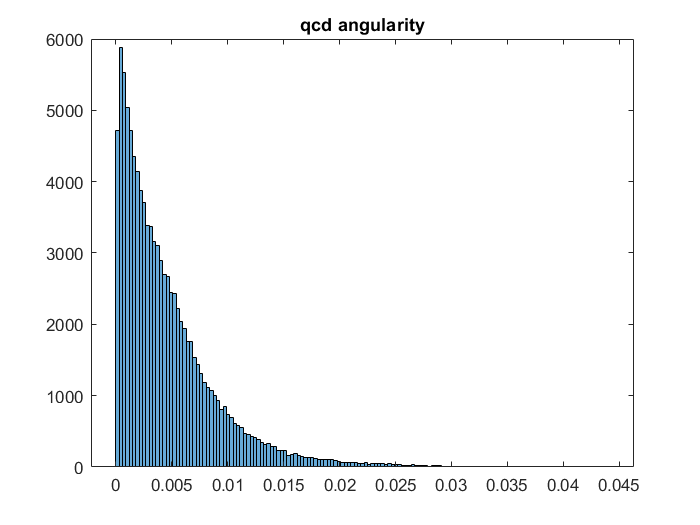

histogram(qcd_angularity)
title('qcd angularity')

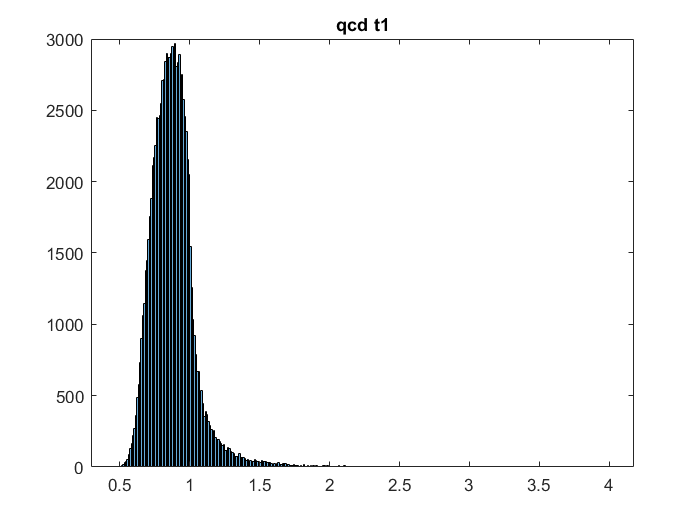

histogram(qcd_t1)
title('qcd t1')

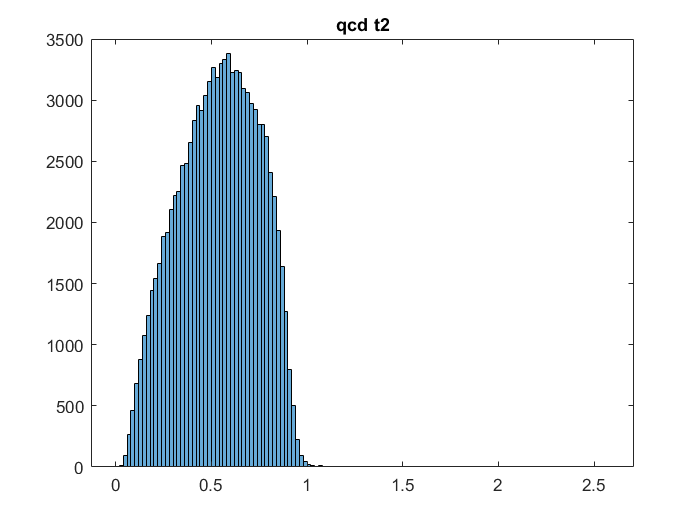

histogram(qcd_t2)
title('qcd t2')

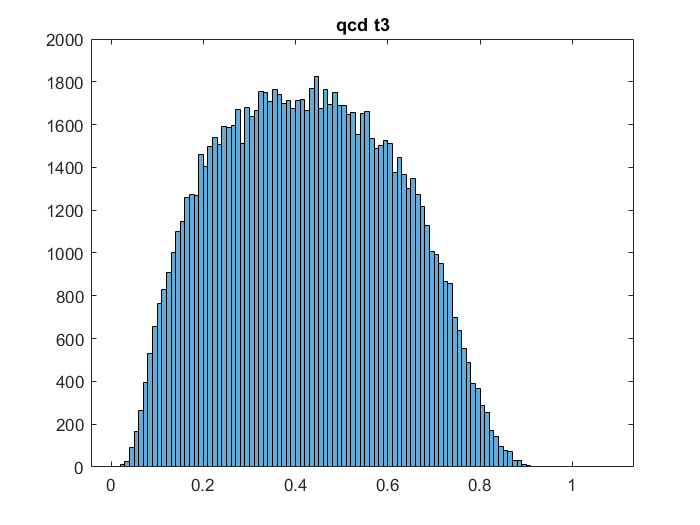

histogram(qcd_t3)
title('qcd t3')

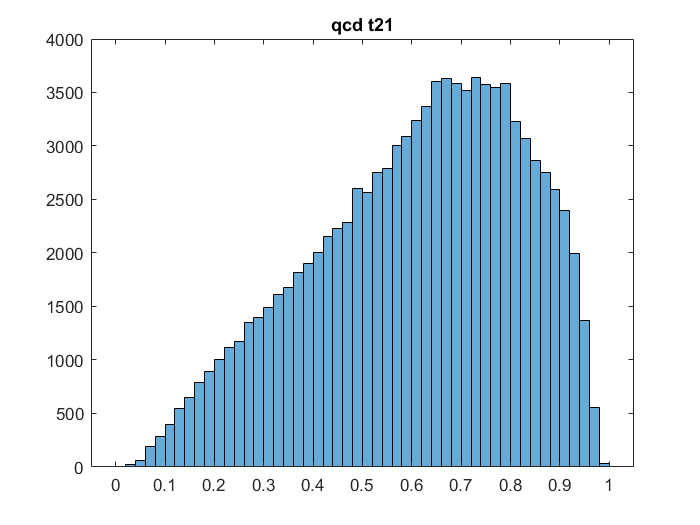

histogram(qcd_t21)
title('qcd t21')

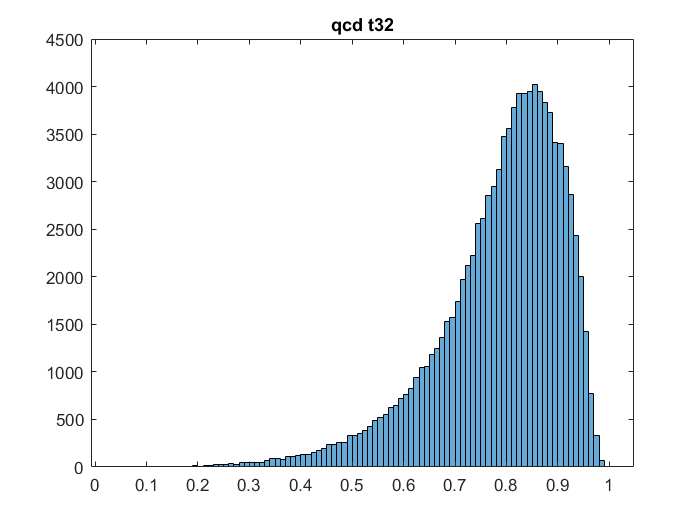

histogram(qcd_t32)
title('qcd t32')

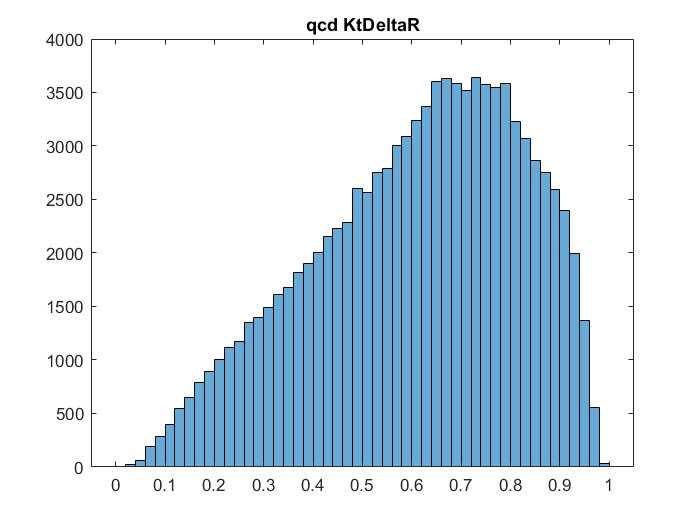

histogram(qcd_KtDeltaR)
title('qcd KtDeltaR')